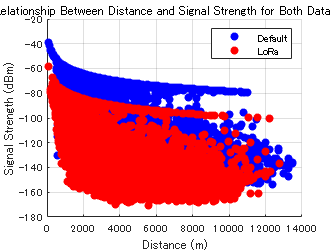

% Load data from both files
data1 = load('data_test.mat');
data2 = load('data_test_lora.mat');

% Extract distances and signal strength values from both data sets
distances1 = data1.all_distances;
signal_strength_values1 = data1.all_signal_strengths;

distances2 = data2.all_distances;
signal_strength_values2 = data2.all_signal_strengths;

% Plot the relationship between distance and signal strength for both sets
figure;

% Plot data from file 1
scatter(distances1, signal_strength_values1, 'b', 'filled', 'DisplayName', 'Default');
hold on;

% Plot data from file 2
scatter(distances2, signal_strength_values2, 'r', 'filled', 'DisplayName', 'LoRa');
grid on;

% Set labels, legend, and title
xlabel('Distance (m)');
ylabel('Signal Strength (dBm)');
title('Relationship Between Distance and Signal Strength for Both Data Sets');
legend();
hold off;